# 设置模型参数

% clc; clear;
% num=[1]; den=[1 1];              % 一阶系统
% den=[1 0.6 1];
% num=[0.04798 0.0464]; den=[1 -1.81 0.9048];
% noiseAmp=0.1;
% sys = tf(num,den);    % 后面在获取过渡时间和截止频率时应该考虑噪声！！
sys=linsys1;

## 时域分析：获取阶跃响应的过渡时间

tmp = stepinfo(sys);
Ts=tmp.SettlingTime

Ts = 78.2415

## 从图上取-3dB

[mag,ph,w]=bode(sys);
mag = 20*log10(squeeze(mag));    % dB
% plot(mag,w)
w0=spline(mag,w,mag(1)-3)

w0 = 0.0499

% w0=spline(mag(35:end),w(35:end),mag(1)-3) % rad/s 观察mag是否单调线性增加

## 计算M序列参数

fM=w0/2/pi     % Hz

fM = 0.0079

delta=0.3/fM   % 取值要小于delta

delta = 37.7736

delta=30;  % 手动取值
Np=[1/(fM*delta),1.2*Ts/delta,1.5*Ts/delta]  % 三个经验公式

Np =     4.1971    3.1297    3.9121


Np=round(max(Np))   % 选择周期大于此结果的M序列

Np = 4

M_OUT=3;
M_Np=max(Np,2^M_OUT-1);       % 此处需要手动选择,不能少于7（最小三个寄存器）
M_xorSEL=[2 3;3 4;3 5;5 6; 4 7];
% [3,4,5,6,7]=[7,15,31,63,127];   IM序列*2
M_XOR=M_xorSEL(M_OUT-2,:);  % 根据NP选择确定M序列的参数
M_Np=2^M_OUT-1;
M_T=M_Np*delta;
IS_M_IM=0;            % 1=M  0=IM
if ~IS_M_IM
    M_Np=2*M_Np;
    M_T=2*M_T;
    disp('采用逆M序列');
end

采用逆M序列


M_d=delta;
if M_T>Ts
    disp('M序列周期大于原系统的过渡时间，符合要求');
else
    disp('请重新计算M或IM序列的参数！')
    return
end

M序列周期大于原系统的过渡时间，符合要求


simTime=11*M_T   % 周期数根据题目要求设置

simTime = 4620

filename='mysysIM.slx';
% open_system(filename);
sim(filename);

% close_system(filename);


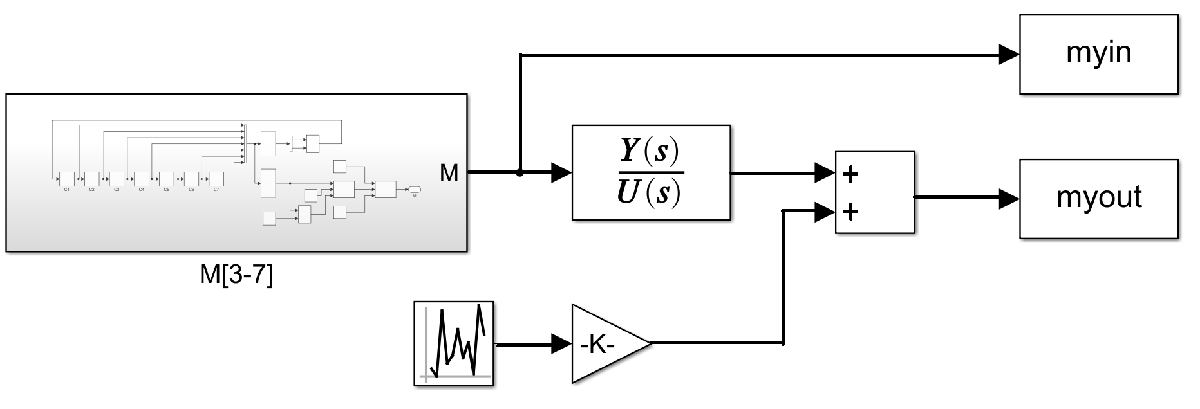

## 手动调用ident进行辨识

% Q=iddata(myout,myin,M_d);
% plot(Q);
% ident

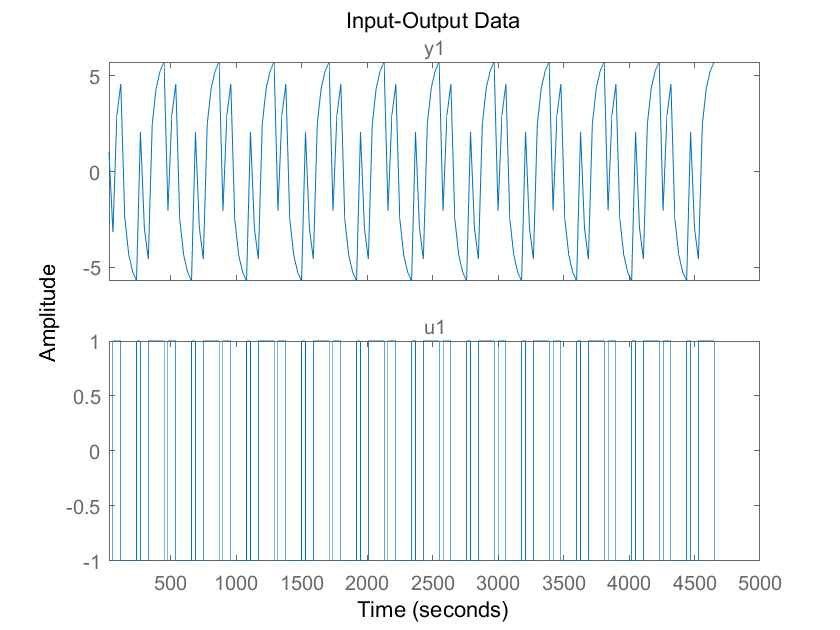

Q=iddata(myout,myin,M_d);
plot(Q);

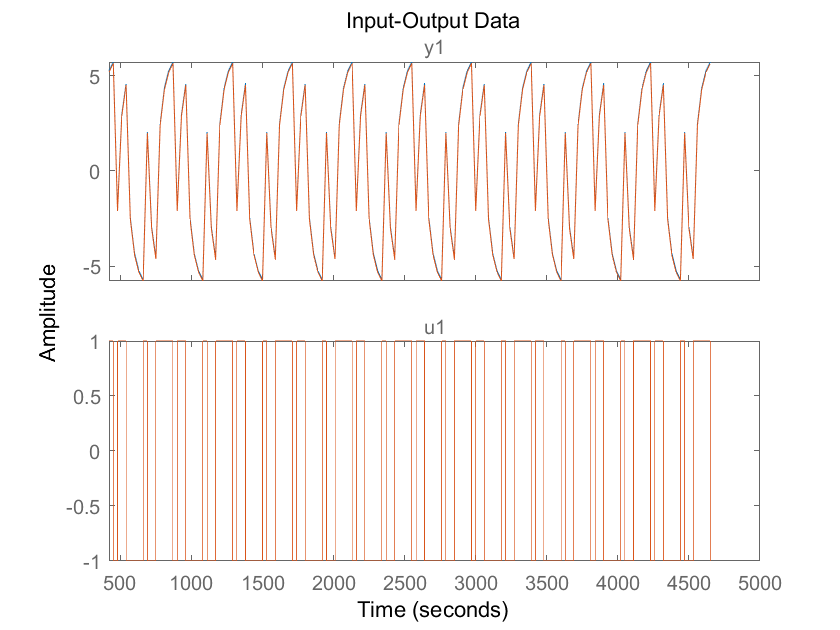

dataStart=M_T/M_d;
Qe = Q([dataStart:end]); % 根据影响去掉第一个周期
Qd=detrend(Qe); plot(Qe,Qd);

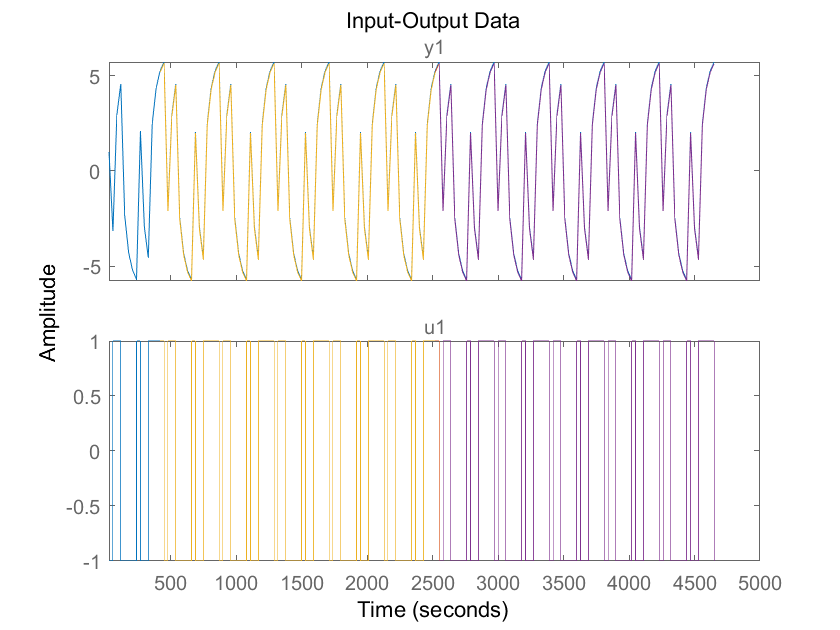

Qde = Qd([1:end/2]);
Qdv = Qd([end/2+1:end]);
plot(Q,Qd,Qde,Qdv);

## ident

NN = struc(1:10,1:10,1:10);
Loss_fun = arxstruc(Qde,Qdv,NN);
% order = selstruc(Loss_fun);
order =[4 4 1]

order =      4     4     1


% order = selstruc(Loss_fun,0);
% order = selstruc(Loss_fun,'aic')
% order_aic = selstruc(Loss_fun,'mdl')

Model = arx(Qde,order)         % AR模型


Model =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
                                                   
  A(z) = 1 - 0.3063 z^-1 + 0.03457 z^-2            
          - 1.127 z^-3 + 0.399 z^-4                
                                                   
                                                   
  B(z) = 3.582 z^-1 + 0.02666 z^-2                 
         + 0.1988 z^-3 - 4.161 z^-4                
                                                   
Sample time: 30 seconds
  
Parameterization:
   Polynomial orders:   na=4
   nb=4   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                        
Estimated using ARX on time domain data "Qde". 
Fit to estimation data: 100% (prediction focus)
FPE: 2.582e-13, MSE: 1.835e-13                 


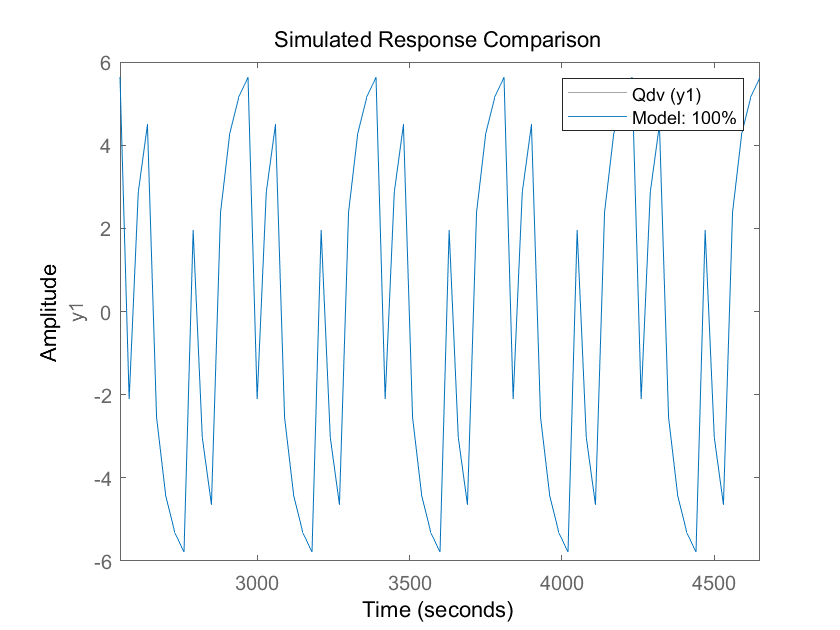

compare(Qdv,Model);	%预测输出与实际输比较

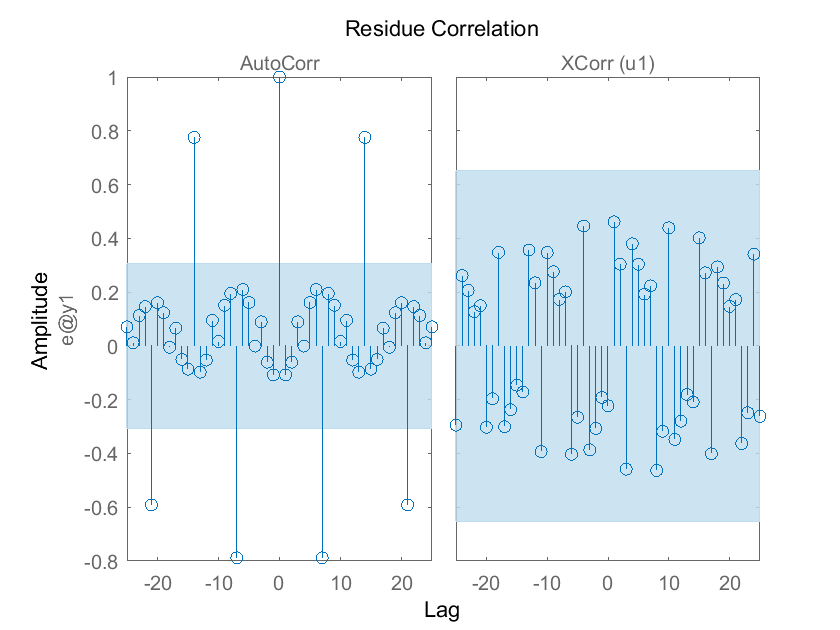

resid(Model,Qdv);	%模型预测误差及相关分析

## 提取模型参数

Model_tf_d=tf(Model)


Model_tf_d =
 
  From input "u1" to output "y1":
                                   
  3.582 z^-1 + 0.02666 z^          
                                   
          -2 + 0.1988 z^-3         
                                   
                       - 4.161 z^-4
                                   
  ---------------------------------
                                   
  1 - 0.3063 z^-1 + 0.03457 z^-2   
                                   
          - 1.127 z^-3 + 0.399 z^-4
                                   
 
Sample time: 30 seconds
Discrete-time transfer function.



Model_tf_c=d2c(Model_tf_d)


Model_tf_c =
 
  From input "u1" to output "y1":
                                   
  0.1981 s^3 - 0.0009805 s^2       
                                   
           + 0.0009488 s - 9.69e-07
                                   
  ---------------------------------
                                   
  s^4 + 0.03063 s^3 + 0.004764 s^2 
                                   
           + 0.0001661 s - 1.32e-12
                                   
 
Continuous-time transfer function.



% Model_tf_c=d2c(Model_tf_d,'tustin')
num=cell2mat(Model_tf_c.num)

num =          0    0.1981   -0.0010    0.0009   -0.0000


den=cell2mat(Model_tf_c.den)

den =     1.0000    0.0306    0.0048    0.0002   -0.0000


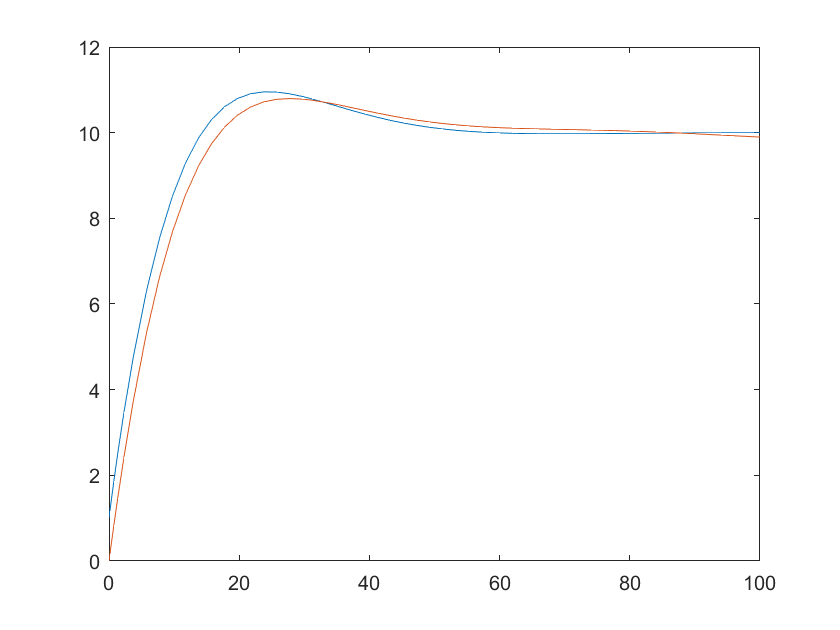

sim('myverify.slx');
plot(simVerifyOut.time,simVerifyOut.signals.values(:,1),simVerifyOut.time,simVerifyOut.signals.values(:,2));%,simVerifyOut.time,simVerifyOut.signals.values(:,3));